cd(fileparts(matlab.desktop.editor.getActiveFilename))
close all; clearvars; clc

load("../../results/trmse_raw.mat")

seq_starts = find(y_within.w_trial==1)+1

seq_starts =      2
    11
    20
    29
    38
    47


seq_stops = find(y_within.w_trial==9)+1;
delta_between = [];
for i=1:length(seq_starts)
seq = y_between(:,seq_starts(i):seq_stops(i));
delta_seq = seq{:,6:9}-seq{:,1:4};
delta_between = [delta_between, delta_seq];
end

d_between = [y_between(:,1), array2table(delta_between)]

d_between = 15×25 table
    b_condition    delta_between1    delta_between2    delta_between3    delta_between4    delta_between5    delta_between6    delta_between7    delta_between8    delta_between9    delta_between10    delta_between11    delta_between12    delta_between13    delta_between14    delta_between15    delta_between16    delta_between17    delta_between18    delta_between19    delta_between20    delta_between21    delta_between22    delta_between23    delta_between24
    ___________    ______________    _________

d_within = y_within(any(y_within.w_trial==(1:4),2),["w_task", "w_gesture", "w_trial"])

d_within = 24×3 table
          w_task              w_gesture        w_trial
    __________________    _________________    _______

    "Machine Learning"    "Co-Activation"         1   
    "Machine Learning"    "Co-Activation"         2   
    "Machine Learning"    "Co-Activation"         3   
    "Machine Learning"    "Co-Activation"         4   
    "Machine Learning"    "Differentiation"       1   
    "Machine Learning"    "Differentiation"       2   
    "Machine Learning"    "Differentiation"       3   
    "Machine Learning"    "Differentiation"       4   
    "Human Learning"      "Co-Activation"         1   
    "Human Learning"      "Co-Activation"         2   
    "Human Learning"      "Co-Activation"         3   
    "Human Learning"      "Co-Activation"         4   
    "Human Learning"      "Differentiation"       1   
    "Human Learning"      "Differentiation"       

### Step 1. Visualize Raw Data in Panels

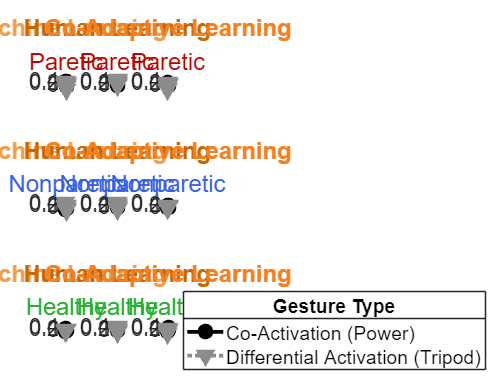

tlo = tiledlayout('flow');
fontsize(tlo, 20, "points")
% tlo.Units = 'inches';
% tlo.OuterPosition = [0 0 17 10.5];
ax_handle_list = [];
for cond = ["par", "xpar", "hlt"]
    y_cond = d_between(d_between.b_condition==cond,2:end);
    for task = ["Machine Learning", "Human Learning", "Co-Adaptive Learning"]
        y_coact = y_cond(:, and(d_within.w_task == task, d_within.w_gesture == "Co-Activation"));
        y_diffact = y_cond(:, and(d_within.w_task == task, d_within.w_gesture == "Differentiation"));
        ax_handle = nexttile;
        ax_handle_list = [ax_handle_list, ax_handle];
        hold on
        plot(y_coact{:,:}', '-ok', 'MarkerFaceColor','k', 'LineWidth',3,'MarkerSize',10 )
        plot(y_diffact{:,:}', ':v', 'MarkerFaceColor',"#8c8c8c", 'LineWidth',3,'MarkerSize',10, 'Color',"#8c8c8c")
        hold off
        title(task)
        switch task
            case "Machine Learning"
                title(task, 'Color', "#f0a150")
            case "Human Learning"
                title(task, 'Color', "#c76706")
            case "Co-Adaptive Learning"
                title(task, 'Color', "#f48020")
        end
        switch cond
            case "par"
                subtitle("Paretic", 'Color', "#b30600")
            case "xpar"
                subtitle("Nonparetic", 'Color', "#3760e3")
            case "hlt"
                subtitle("Healthy", 'Color', "#29af34")
        end
        xticks(1:9)
        yticks(0:0.2:0.8)
    end
end
legend_handle = legend(["Co-Activation (Power)",repmat("", 1,4), "Differential Activation (Tripod)"], "Location","eastoutside");
title(legend_handle, "Gesture Type")
linkaxes(ax_handle_list, 'xy')
ylim(1.1*[min(delta_between,[], 'all'), max(delta_between,[], 'all')])
xlim([0 5])
% title(tlo, sprintf("%s Vs. Trial Count", upper(metric_type)))
set(ax_handle_list, 'FontSize', 18)

[ctrlr_dict, ctrlr_keys, cond_keys] = table_to_dict(d_between, d_within);
[data_mean, data_sem, N] = compute_inf_stats(ctrlr_dict)

data_mean =     0.0526   -0.0059   -0.0058
   -0.0480   -0.0615   -0.0518
   -0.0780   -0.0617   -0.0708


data_sem =     0.0250    0.0175    0.0177
    0.0233    0.0274    0.0104
    0.0236    0.0114    0.0166


N = 40

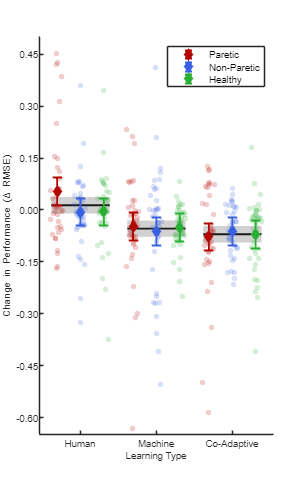

fig_h = figure;
set(fig_h, 'Renderer', 'painters');
fig_aspect = "IEEE-1"; % IEEE-1, IEEE-2, PPT
if fig_aspect == "IEEE-1"
set(fig_h, "Units","centimeters", "Position", [15, 5, 8.89, 14.38])%IEEE
cap_size = 8; mk_size = 20;mk_size_err = 6;ln_width = 1.5;%IEEE
fig_fontsize = 8;
elseif fig_aspect == "PPT"
set(fig_h, "Units","inches", "Position", [6, 3, 10, 7.5])%PPT
cap_size = 15; mk_size = 50;mk_size_err = 10;ln_width = 3;%PPT
fig_fontsize = 24;
else
    error("Aspect (%s) not implemented", fig_aspect);
end

color_names = ["red", "blue", "green", "gray", "black"];
color_vals = {[179,6,0]/255, [55,96,227]/255, [41,175,52]/255, [153,153,153]/255, [26,26,26]/255};
color_scheme = dictionary(color_names, color_vals);
mk_alpha = 0.20;
xj_width = 0.55;
sem_factor = 1;

hold on
x_locs_intra = linspace(1.00, 3.00, 3);
x_locs_inter_dist = 1.25;
x_locs_offset = diff(x_locs_intra([1,end]))+x_locs_inter_dist;
x_locs = [x_locs_intra, x_locs_intra + x_locs_offset, x_locs_intra + 2*x_locs_offset];
% x_locs = [1.00,1.75,2.50,3.50,4.25,5.00,6.00,6.75,7.50];

patch_opts = {'FaceColor', color_scheme{"gray"}, 'EdgeColor', 'none', 'FaceAlpha', 0.45};
group_x_offset = 0.25;
group_x = [x_locs(1)-group_x_offset, x_locs(3)+group_x_offset];
group_mean = ones(size(group_x))*mean([ctrlr_dict{"Human Learning"}{"paretic"};ctrlr_dict{"Human Learning"}{"nonparetic"}; ctrlr_dict{"Human Learning"}{"healthy"}]);
group_sem = ones(size(group_x))*std([ctrlr_dict{"Human Learning"}{"paretic"};ctrlr_dict{"Human Learning"}{"nonparetic"}; ctrlr_dict{"Human Learning"}{"healthy"}])/sqrt(3*N)*sem_factor;
patch_x = [group_x, fliplr(group_x)];
patch_y = [group_mean+group_sem, fliplr(group_mean-group_sem)];
patch_y = [ones(size(group_x))*0.0374018, ones(size(group_x))*-0.0100644]; %HARDCODED FROM MASA'S ANALYSIS
patch(patch_x, patch_y, 1, patch_opts{:});
plot(group_x, group_mean, 'LineWidth', ln_width, 'Color', color_scheme{"black"})

group_x = [x_locs(4)-group_x_offset, x_locs(6)+group_x_offset];
group_mean = ones(size(group_x))*mean([ctrlr_dict{"Machine Learning"}{"paretic"};ctrlr_dict{"Machine Learning"}{"nonparetic"}; ctrlr_dict{"Machine Learning"}{"healthy"}]);
group_sem = ones(size(group_x))*std([ctrlr_dict{"Machine Learning"}{"paretic"};ctrlr_dict{"Machine Learning"}{"nonparetic"}; ctrlr_dict{"Machine Learning"}{"healthy"}])/sqrt(3*N)*sem_factor;
patch_x = [group_x, fliplr(group_x)];
patch_y = [group_mean+group_sem, fliplr(group_mean-group_sem)];
patch_y = [ones(size(group_x))*-0.0300324, ones(size(group_x))*-0.0774986]; %HARDCODED FROM MASA'S ANALYSIS
patch(patch_x, patch_y, 1, patch_opts{:});
plot(group_x, group_mean, 'LineWidth', ln_width, 'Color', color_scheme{"black"})

group_x = [x_locs(7)-group_x_offset, x_locs(9)+group_x_offset];
group_mean = ones(size(group_x))*mean([ctrlr_dict{"Co-Adaptive Learning"}{"paretic"};ctrlr_dict{"Co-Adaptive Learning"}{"nonparetic"}; ctrlr_dict{"Co-Adaptive Learning"}{"healthy"}]);
group_sem = ones(size(group_x))*std([ctrlr_dict{"Co-Adaptive Learning"}{"paretic"};ctrlr_dict{"Co-Adaptive Learning"}{"nonparetic"}; ctrlr_dict{"Co-Adaptive Learning"}{"healthy"}])/sqrt(3*N)*sem_factor;
patch_x = [group_x, fliplr(group_x)];
patch_y = [group_mean+group_sem, fliplr(group_mean-group_sem)];
patch_y = [ones(size(group_x))*-0.0464255, ones(size(group_x))*-0.0938916]; %HARDCODED FROM MASA'S ANALYSIS
patch(patch_x, patch_y, 1, patch_opts{:});
plot(group_x, group_mean, 'LineWidth', ln_width, 'Color', color_scheme{"black"})

swarm_opts = {'filled', 'MarkerFaceAlpha', mk_alpha, 'XJitter', 'randn', 'XJitterWidth', xj_width};
swarmchart(x_locs(1)*ones(N,1), ctrlr_dict{"Human Learning"}{"paretic"}, mk_size, color_scheme{"red"}, swarm_opts{:})
swarmchart(x_locs(2)*ones(N,1), ctrlr_dict{"Human Learning"}{"nonparetic"}, mk_size, color_scheme{"blue"}, swarm_opts{:})
swarmchart(x_locs(3)*ones(N,1), ctrlr_dict{"Human Learning"}{"healthy"}, mk_size, color_scheme{"green"}, swarm_opts{:})

swarmchart(x_locs(4)*ones(N,1), ctrlr_dict{"Machine Learning"}{"paretic"}, mk_size, color_scheme{"red"}, swarm_opts{:})
swarmchart(x_locs(5)*ones(N,1), ctrlr_dict{"Machine Learning"}{"nonparetic"}, mk_size, color_scheme{"blue"}, swarm_opts{:})
swarmchart(x_locs(6)*ones(N,1), ctrlr_dict{"Machine Learning"}{"healthy"}, mk_size, color_scheme{"green"}, swarm_opts{:})

swarmchart(x_locs(7)*ones(N,1), ctrlr_dict{"Co-Adaptive Learning"}{"paretic"}, mk_size, color_scheme{"red"}, swarm_opts{:})
swarmchart(x_locs(8)*ones(N,1), ctrlr_dict{"Co-Adaptive Learning"}{"nonparetic"}, mk_size, color_scheme{"blue"}, swarm_opts{:})
swarmchart(x_locs(9)*ones(N,1), ctrlr_dict{"Co-Adaptive Learning"}{"healthy"}, mk_size, color_scheme{"green"}, swarm_opts{:})

ebar_opts = {'LineStyle', 'none', 'LineWidth', ln_width, 'Marker', 'd', 'MarkerSize', mk_size_err, 'CapSize', cap_size};
ebar_par = [std(ctrlr_dict{"Human Learning"}{"paretic"}); std(ctrlr_dict{"Machine Learning"}{"paretic"}); std(ctrlr_dict{"Co-Adaptive Learning"}{"paretic"})]/sqrt(N)*sem_factor;
ebar_par = ones(size(ebar_par))*0.040258;
plt_h(1) = errorbar(x_locs(1:3:9)', ...
           [mean(ctrlr_dict{"Human Learning"}{"paretic"}); mean(ctrlr_dict{"Machine Learning"}{"paretic"}); mean(ctrlr_dict{"Co-Adaptive Learning"}{"paretic"})], ...
           ebar_par, ...
           ebar_opts{:}, 'Color', color_scheme{"red"}, 'MarkerFaceColor', color_scheme{"red"});

ebar_xpar = [std(ctrlr_dict{"Human Learning"}{"nonparetic"}); std(ctrlr_dict{"Machine Learning"}{"nonparetic"}); std(ctrlr_dict{"Co-Adaptive Learning"}{"nonparetic"})]/sqrt(N)*sem_factor;
ebar_xpar = ones(size(ebar_xpar))*0.040258;
plt_h(2) = errorbar(x_locs(2:3:9)', ...
           [mean(ctrlr_dict{"Human Learning"}{"nonparetic"}); mean(ctrlr_dict{"Machine Learning"}{"nonparetic"}); mean(ctrlr_dict{"Co-Adaptive Learning"}{"nonparetic"})], ...
           ebar_xpar, ...
           ebar_opts{:}, 'Color', color_scheme{"blue"}, 'MarkerFaceColor', color_scheme{"blue"});

ebar_healthy = [std(ctrlr_dict{"Human Learning"}{"healthy"}); std(ctrlr_dict{"Machine Learning"}{"healthy"}); std(ctrlr_dict{"Co-Adaptive Learning"}{"healthy"})]/sqrt(N)*sem_factor;
ebar_healthy = ones(size(ebar_healthy))*0.040258;
plt_h(3) = errorbar(x_locs(3:3:9)', ...
           [mean(ctrlr_dict{"Human Learning"}{"healthy"}); mean(ctrlr_dict{"Machine Learning"}{"healthy"}); mean(ctrlr_dict{"Co-Adaptive Learning"}{"healthy"})], ...
           ebar_healthy, ...
           ebar_opts{:}, 'Color', color_scheme{"green"}, 'MarkerFaceColor', color_scheme{"green"});
hold off

xlim(x_locs([1,end]) + 3*[-group_x_offset, group_x_offset])
xticks(x_locs(2:3:9))
xticklabels(["Human", "Machine", "Co-Adaptive"])
xlabel("Learning Type")

yticks(-0.6:0.15:0.5)
ytickformat('%0.2f')
ylabel("Change in Performance (\Delta RMSE)")

if fig_aspect == "IEEE-1"
ylim([-0.65, 0.50])%IEEE
legend(plt_h, "Paretic", "Non-Paretic", "Healthy") %IEEE
elseif fig_aspect == "PPT"
ylim([-0.30, 0.31])%PPT
else
    error("Aspect (%s) not implemented", fig_aspect);
end
fontsize(fig_h, fig_fontsize,"points")%PPT

% title("Learning Effect")

print(fig_h, '../../results/eps-figs/delta-rmse', '-depsc', '-r600', '-vector')

figure
raincloud_data = [
    [ctrlr_dict{"Human Learning"}{"paretic"};ctrlr_dict{"Human Learning"}{"nonparetic"};ctrlr_dict{"Human Learning"}{"healthy"}],...
    [ctrlr_dict{"Machine Learning"}{"paretic"};ctrlr_dict{"Machine Learning"}{"nonparetic"};ctrlr_dict{"Machine Learning"}{"healthy"}],...
    [ctrlr_dict{"Co-Adaptive Learning"}{"paretic"};ctrlr_dict{"Co-Adaptive Learning"}{"nonparetic"};ctrlr_dict{"Co-Adaptive Learning"}{"healthy"}]
]

raincloud_data =    -0.1704    0.0284   -0.0777
   -0.0333    0.1934   -0.0406
    0.0381   -0.1277   -0.1543
   -0.1270   -0.0994   -0.1494
    0.1121   -0.1070   -0.0904
   -0.0494   -0.0756    0.0422
   -0.0272    0.2331    0.0183
    0.0094   -0.3093   -0.0618
   -0.0815   -0.0762   -0.2341
    0.0626   -0.0387    0.0786


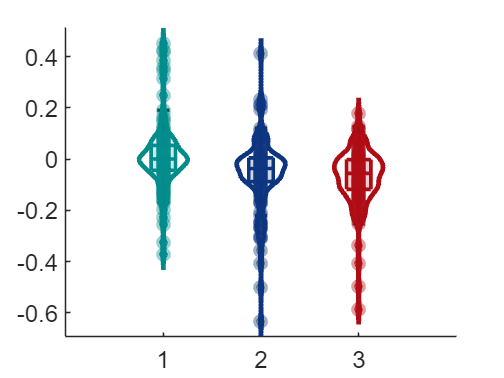

ans =   Figure (36) with properties:

      Number: 36
        Name: ''
       Color: [1 1 1]
    Position: [680 458 560 420]
       Units: 'pixels'

  Show all properties


frm_dviz_utils.plot_rainclouds(raincloud_data, 'quadruple', 'vase', 0.02)

### Export to R

r_dataframe = [];
offset = 0;
for i=1:height(d_between)
    if or(d_between{i,1} == "par", d_between{i,1} == "xpar")
        p_id = i-1+mod(i,2);
    else
        p_id = i;
    end
    p_tbl = array2table([d_between{i,2:end}', repmat(p_id, height(d_within),1), repmat(d_between{i,1}, height(d_within),1), d_within{:,:}], ...
        "VariableNames", ["rmse", "p_id", "p_cond", "task_type", "gesture_type", "trial_num"]);
    r_dataframe = [r_dataframe; p_tbl];
end

r_dataframe = convertvars(r_dataframe, ["rmse"], 'double');

r_dataframe = convertvars(r_dataframe, ["trial_num", "p_id"], 'double');
r_dataframe = convertvars(r_dataframe, ["gesture_type", "task_type", "p_cond"], 'categorical');
r_dataframe = r_dataframe(:,{'rmse' 'trial_num' 'gesture_type' 'task_type' 'p_cond', 'p_id'})

r_dataframe = 360 6 table
       rmse       trial_num     gesture_type         task_type        p_cond    p_id
    __________    _________    _______________    ________________    ______    ____

      0.028416        1        Co-Activation      Machine Learning     par       1  
     -0.075632        2        Co-Activation      Machine Learning     par       1  
     -0.085248        3        Co-Activation      Machine Learning     par       1  
     -0.074761        4        Co-Activation      Machine Learning     par       1  
      0.028847        1        Differentiation    Machine Learning     par       1  
     -0.021716        2        Differentiation    Machine Learning     par       1  
      -0.14012        3        Differentiation    Machine Learning     par       1  
    

writetable(r_dataframe, '../../temp-data/rdf_rmse_delta_10.csv','WriteMode','overwrite')

long_tbl = r_dataframe(:, ["p_id","p_cond","task_type","trial_num","gesture_type","rmse"]);
long_tbl.Properties.VariableNames = ["Participant ID", "Neurological Condition", "Decoder Type", "Trial ID", "Gesture Type", "Learning Effect (change in RMSE)"];
long_tbl.("Neurological Condition")(long_tbl.("Neurological Condition")=="par") = "Paretic";
long_tbl.("Neurological Condition")(long_tbl.("Neurological Condition")=="xpar") = "Nonparetic";
long_tbl.("Neurological Condition")(long_tbl.("Neurological Condition")=="hlt") = "Healthy";
long_tbl.("Participant ID")(long_tbl.("Participant ID")==3) = 2;
long_tbl.("Participant ID")(long_tbl.("Participant ID")==5) = 3;
long_tbl.("Participant ID")(long_tbl.("Participant ID")==7) = 4;
long_tbl.("Participant ID")(long_tbl.("Participant ID")==9) = 5;
long_tbl.("Participant ID")(long_tbl.("Participant ID")==11) = 6;
long_tbl.("Participant ID")(long_tbl.("Participant ID")==12) = 7;
long_tbl.("Participant ID")(long_tbl.("Participant ID")==13) = 8;
long_tbl.("Participant ID")(long_tbl.("Participant ID")==14) = 9;
long_tbl.("Participant ID")(long_tbl.("Participant ID")==15) = 10

long_tbl = 360 6 table
    Participant ID    Neurological Condition      Decoder Type      Trial ID     Gesture Type      Learning Effect (change in RMSE)
    ______________    ______________________    ________________    ________    _______________    ________________________________

          1                  Paretic            Machine Learning       1        Co-Activation                   0.028416           
          1                  Paretic            Machine Learning       2        Co-Activation                  -0.075632           
          1                  Paretic            Machine Learning       3        Co-Activation                  -0.085248           
          1                  Paretic            Machine Learning       4        Co-Activation                  -

long_tbl.("Neurological Condition") = categorical(long_tbl.("Neurological Condition"), {'Paretic', 'Nonparetic', 'Healthy'}, "Ordinal",true);
long_tbl.("Decoder Type") = categorical(long_tbl.("Decoder Type"), {'Machine Learning', 'Co-Adaptive Learning', 'Human Learning'}, "Ordinal",true);
long_tbl.("Gesture Type") = categorical(long_tbl.("Gesture Type"), {'Co-Activation', 'Differentiation'}, "Ordinal",true)

long_tbl = 360 6 table
    Participant ID    Neurological Condition      Decoder Type      Trial ID     Gesture Type      Learning Effect (change in RMSE)
    ______________    ______________________    ________________    ________    _______________    ________________________________

          1                  Paretic            Machine Learning       1        Co-Activation                   0.028416           
          1                  Paretic            Machine Learning       2        Co-Activation                  -0.075632           
          1                  Paretic            Machine Learning       3        Co-Activation                  -0.085248           
          1                  Paretic            Machine Learning       4        Co-Activation                  -

long_tbl = sortrows(long_tbl, {'Participant ID', 'Neurological Condition', 'Decoder Type', 'Trial ID', 'Gesture Type'})

long_tbl = 360 6 table
    Participant ID    Neurological Condition        Decoder Type        Trial ID     Gesture Type      Learning Effect (change in RMSE)
    ______________    ______________________    ____________________    ________    _______________    ________________________________

          1                  Paretic            Machine Learning           1        Co-Activation                  0.028416            
          1                  Paretic            Machine Learning           1        Differentiation                0.028847            
          1                  Paretic            Machine Learning           2        Co-Activation                 -0.075632            
          1                  Paretic            Machine Learning           2        Differen

writetable(long_tbl, '../../results/long-tables/rmse_learning_effect.csv','WriteMode','overwrite')

### 2-Way ANOVA

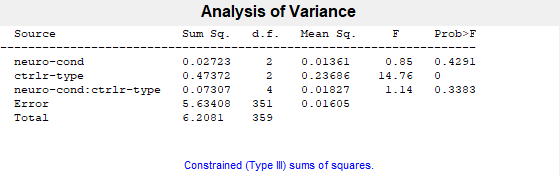

[pvals,anova_tbl,stats, terms] = anovan(r_dataframe{:,"rmse"}, ...
    {r_dataframe{:,"p_cond"}, r_dataframe{:,"task_type"}}, ...
    'varnames',["neuro-cond", "ctrlr-type"], ...
    'model',2);

pvals

pvals =     0.4291
    0.0000
    0.3383


terms = terms(2,:)

terms =      0     1


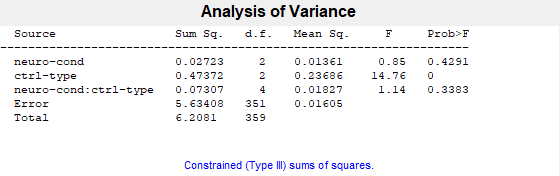

[pvals,anova_tbl,stats, terms] = anovan(r_dataframe{:,"rmse"}, ...
    {r_dataframe{:,"p_cond"}, r_dataframe{:,"task_type"}}, ...
    'varnames',["neuro-cond", "ctrl-type"], ...
    'model',2);

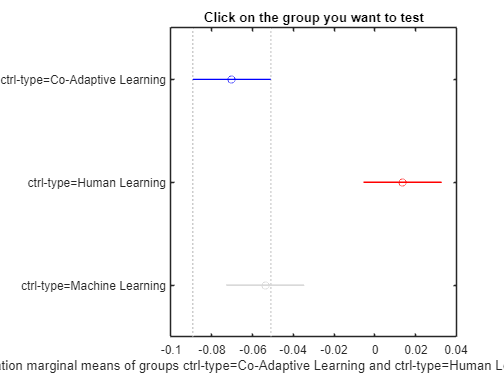

figure
[results, estimates, ~, group_names] = multcompare(stats, "Dimension",[2]);

format short
tbl = array2table(results,"VariableNames", ...
    ["Group","Control Group","Lower Limit","Difference","Upper Limit","P-value"]);
tbl.("Group") = group_names(tbl.("Group"));
tbl.("Control Group") = group_names(tbl.("Control Group"))

tbl = 3 6 table
                  Group                           Control Group             Lower Limit    Difference    Upper Limit     P-value  
    __________________________________    ______________________________    ___________    __________    ___________    __________

    {'ctrl-type=Co-Adaptive Learning'}    {'ctrl-type=Human Learning'  }      -0.12216     -0.083827      -0.045493     8.8973e-07
    {'ctrl-type=Co-Adaptive Learning'}    {'ctrl-type=Machine Learning'}     -0.054727     -0.016393       0.021941        0.57542
    {'ctrl-type=Human Learning'      }    {'ctrl-type=Machine Learning'}        0.0291      0.067434        0.10577     0.00011083


estimates

estimates =    -0.0702    0.0116
    0.0137    0.0116
   -0.0538    0.0116
